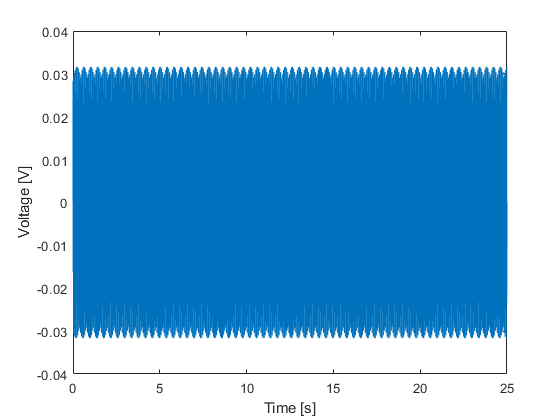

clear all

fs = 1000e6;
tmax = 25e-6;
t = (0:1/fs:tmax).';

nwaves = 5;
f = linspace(50,180,nwaves)'*1e6;
a = linspace(1,12,nwaves)'*1e-3;

x = zeros(size(t));
for i=1:nwaves
    x = x + a(i)*sin(2*pi*f(i)*t);
end
% x = x+0.001;

[f,s,n,u] = calc_fft2(x,fs,'dimFlag',1,'unitFlag','amp');

plot(t*1e6,x),xlabel('Time [s]'),ylabel('Voltage [V]')

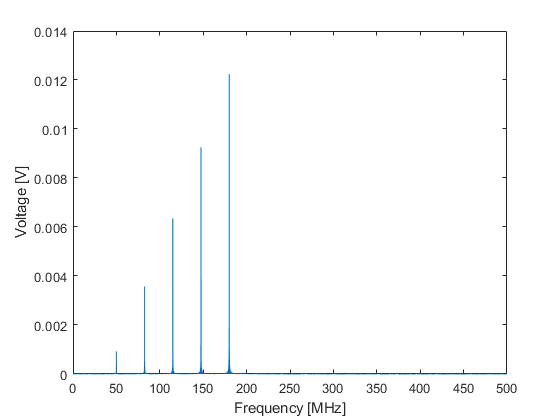

plot(f*1e-6,abs(s)),xlabel('Frequency [MHz]'),ylabel('Voltage [V]')


% xlim([34 267])
% ylim([-0.0028 0.0135])